# Plotting the error surface

clear all;
close all;
clc;

load error_loc_2MU_grid_0_1



#### Fontsize

fontsize=15;


#### Depicting the Scenario

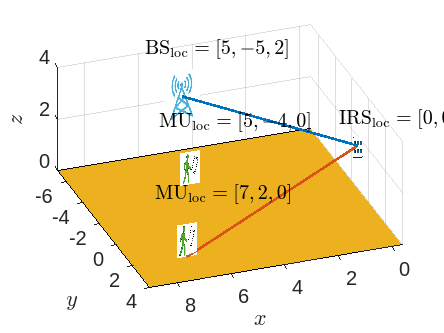

figure;
%depicting the MU
rot_az=20*pi/360;
img = imread('figures/MU.jpg');
[row,col]=size(img);
xImage = [pos_rx_1(1)-row/col*rx_size*cos(rot_az) pos_rx_1(1)+row/col*rx_size*cos(rot_az);...
          pos_rx_1(1)-row/col*rx_size*cos(rot_az) pos_rx_1(1)+row/col*rx_size*cos(rot_az)]; % The y data for the image corners

yImage = [pos_rx_1(2) pos_rx_1(2);...
          pos_rx_1(2) pos_rx_1(2)]; % The x data for the image corners


zImage = [pos_rx_1(3)+1.5*rx_size/2 pos_rx_1(3)+1.5*rx_size/2;...
          pos_rx_1(3) pos_rx_1(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none'); hold on;
txt=strcat("$$\mathrm{MU}_\mathrm{loc}=[",num2str(pos_rx_1(1)),",",num2str(pos_rx_1(2)),",",num2str(pos_rx_1(3)),"]$");
text(pos_rx_1(1)+rx_size,pos_rx_1(2)+rx_size,pos_rx_1(3)+2*rx_size,txt,'Interpreter','latex','FontSize',fontsize);

%second MU
xImage = [pos_rx_2(1)-row/col*rx_size*cos(rot_az) pos_rx_2(1)+row/col*rx_size*cos(rot_az);...
          pos_rx_2(1)-row/col*rx_size*cos(rot_az) pos_rx_2(1)+row/col*rx_size*cos(rot_az)]; % The y data for the image corners

yImage = [pos_rx_2(2) pos_rx_2(2);...
          pos_rx_2(2) pos_rx_2(2)]; % The x data for the image corners


zImage = [pos_rx_2(3)+1.5*rx_size/2 pos_rx_2(3)+1.5*rx_size/2;...
          pos_rx_2(3) pos_rx_2(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none'); hold on;
txt=strcat("$$\mathrm{MU}_\mathrm{loc}=[",num2str(pos_rx_2(1)),",",num2str(pos_rx_2(2)),",",num2str(pos_rx_2(3)),"]$");
text(pos_rx_2(1)+rx_size,pos_rx_2(2)+rx_size,pos_rx_2(3)+2*rx_size,txt,'Interpreter','latex','FontSize',fontsize);


%depicting the BS
rot_az=0*pi/360;
% rot_el=30*2*pi/360;

img = imread('figures/BS.jpg');
[row,col]=size(img);
xImage = [pos_tx(1)-row/col*tx_size_img*cos(rot_az) pos_tx(1)+row/col*tx_size_img*cos(rot_az);...
          pos_tx(1)-row/col*tx_size_img*cos(rot_az) pos_tx(1)+row/col*tx_size_img*cos(rot_az)]; % The y data for the image corners
yImage = [pos_tx(2) pos_tx(2);...
          pos_tx(2) pos_tx(2)]; % The x data for the image corners
zImage = [pos_tx(3)+tx_size_img pos_tx(3)+tx_size_img;...
          pos_tx(3) pos_tx(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none');
txt=strcat("$\mathrm{BS}_\mathrm{loc}=[",num2str(pos_tx(1)),",",num2str(pos_tx(2)),",",num2str(pos_tx(3)),"]$");
text(pos_tx(1)+tx_size_img,pos_tx(2)+tx_size_img,pos_tx(3)+2*tx_size_img,txt,'Interpreter','latex','FontSize',fontsize);

xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
set(gca,'FontSize',fontsize);

%depicting the IRS

IRS_scale=0.5;
rot_az=150*pi/360;
img = imread('figures/IRS.jpg');
xImage = [pos_IRS(1)-row/col*tx_size_img*cos(rot_az) pos_IRS(1)+row/col*tx_size_img*cos(rot_az);...
          pos_IRS(1)-row/col*tx_size_img*cos(rot_az) pos_IRS(1)+row/col*tx_size_img*cos(rot_az)]; % The X data for the image corners

yImage = [pos_IRS(2)+IRS_scale*IRS_size pos_IRS(2)-IRS_scale*IRS_size;...
          pos_IRS(2)+IRS_scale*IRS_size pos_IRS(2)-IRS_scale*IRS_size]; % The Y data for the image corners


zImage = [pos_IRS(3)+3*IRS_scale*col/row*IRS_size pos_IRS(3)+3*IRS_scale*col/row*IRS_size;...
          pos_IRS(3)-1*IRS_scale*col/row*IRS_size pos_IRS(3)-1*IRS_scale*col/row*IRS_size];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none');
txt=strcat("$\mathrm{IRS}_\mathrm{loc}=[",num2str(pos_IRS(1)),",",num2str(pos_IRS(2)),",",num2str(pos_IRS(3)),"]$");
text(pos_IRS(1)+2*IRS_size,pos_IRS(2)-10*IRS_size,pos_IRS(3)+2*IRS_size*col/row,txt,'Interpreter','latex','FontSize',fontsize);

%depicting the line from the BS to the IRS
plot3([pos_tx(1) pos_IRS(1)],[pos_tx(2) pos_IRS(2)], [pos_tx(3)+tx_size_img/2 pos_IRS(3)+IRS_size*2],'LineWidth',2);

%depicting the line from the IRS to the MU
plot3([pos_rx_1(1) pos_IRS(1)],[pos_rx_1(2) pos_IRS(2)], [pos_rx_1(3) pos_IRS(3)+IRS_size*2],'LineWidth',2);

%depicting the ground plane
rect=rectangle('Position',[min([pos_tx(1),pos_IRS(1),pos_rx_1(1)])-max([tx_size_img,IRS_size,rx_size])...
                           min([pos_tx(2),pos_IRS(2),pos_rx_1(2)])-max([tx_size_img,IRS_size,rx_size]) ...
                           max([pos_tx(1),pos_IRS(1),pos_rx_1(1)])-min([pos_tx(1),pos_IRS(1),pos_rx_1(1)])+2*max([tx_size_img,IRS_size,rx_size]) ...
                           max([pos_tx(2),pos_IRS(2),pos_rx_1(2)])-min([pos_tx(2),pos_IRS(2),pos_rx_1(2)])+2*max([tx_size_img,IRS_size,rx_size]) ...
                           ],'FaceColor',"#EDB120");


axis([min([pos_tx(1),pos_IRS(1),pos_rx_1(1)])-3*min([tx_size_img,IRS_size,rx_size]) ...
      max([pos_tx(1),pos_IRS(1),pos_rx_1(1)])+max([tx_size_img,IRS_size,rx_size])...
      min([pos_tx(2),pos_IRS(2),pos_rx_1(2)])-max([tx_size_img,IRS_size,rx_size]) ...
      max([pos_tx(2),pos_IRS(2),pos_rx_1(2)])+max([tx_size_img,IRS_size,rx_size])...
      min([pos_tx(3),pos_IRS(3),pos_rx_1(3)]) ...
      max([pos_tx(3),pos_IRS(3),pos_rx_1(3)])+max([tx_size_img,IRS_size,rx_size])]);


xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
set(gca,'FontSize',fontsize);

view([-200 50])

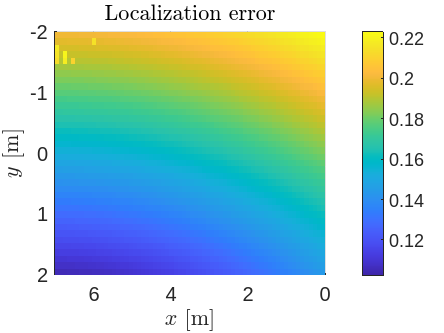


figure;
x=linspace(x_min,x_max,ceil((x_max-x_min)/grid_size)-3);
y=linspace(y_min,y_max,ceil((y_max-y_min)/grid_size)-1);

[X,Y] = meshgrid(x,y);
s=surf(X',Y',abs(error_loc(2:end-2,2:end)));
s.EdgeColor = 'none';
colorbar
xlabel('$x$ [m]','Interpreter','latex');
ylabel('$y$ [m]','Interpreter','latex');
zlabel('Error [m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

axis([x_min ...
      x_max...
      y_min ...
      y_max...
      min([min(error_loc),min(error_loc),min(error_loc)]) ...
      max([max(error_loc),max(error_loc),max(error_loc)])]);

view([-180 90]);
title({'Localization error'},'Interpreter','latex')

% view([-200 50])